# RoadRunner - Use of sensor model by Simulink cosimulation

## Clean up variables and RoadRunner

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;

% English: Flag to enable solution mode; when True, the program executes the pre-written correct code.
isSolutionMode = true

isSolutionMode = logical
   1


## Start RoadRunner from MATLAB

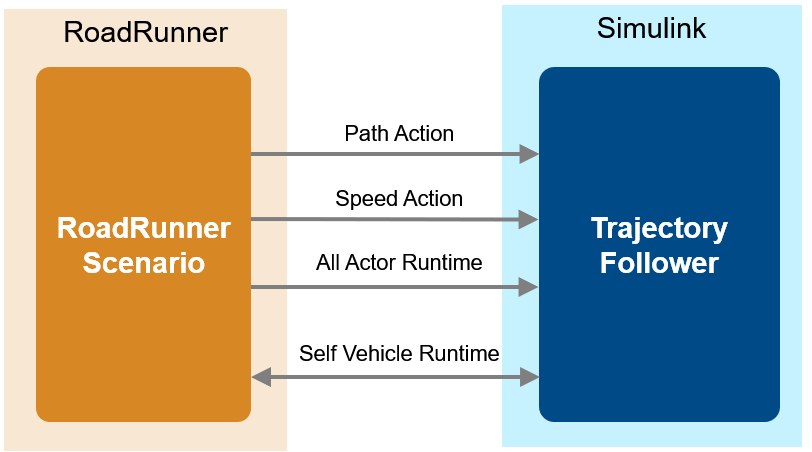

% If you are using a version earlier than R2024a, open the example with the following command and run it.
% openExample('driving/AddSensorsToRoadRunnerScenarioUsingSimulinkExample')
rrApp = roadrunner();
rrProjectPath = rrApp.status.Project.Filename;
copyfile("RRfiles/TrajectoryCutInWithVariables.rrscenario",fullfile(rrProjectPath,"Scenarios/"));

% Start the scenario. The scene is linked to the scenario, so it will open automatically
rrApp.openScenario("TrajectoryCutInWithVariables");

% Align the execution step size of RoadRunner and Simulink
simStepSize = 0.1;
rrSim = rrApp.createSimulation();

Connection status: 1
Connected to RoadRunner Scenario server on localhost:45072, with client id {0f170181-5fc5-4bb4-accd-cf10f036dba5}


setRRSCameraMode(rrApp, "follow", actorID=2);

rrSim.set("StepSize", simStepSize);

% Define a bus object to get RoadRunner information in Simulink.
% To support Reader and Writer blocks, some bus objects must be loaded
load(fullfile(matlabroot,'toolbox','driving','drivingdata','rrScenarioSimTypes.mat'));
load("busDefinitionsForRRSim.mat"); % Read the bus object for sensor simulation

% Vehicle position change constant
gainArg = [
    1 0 0 0.5;
    0 1 0 0.1;
    0 0 1 0;
    0 0 0 1];

% Open the Simulink model
model_name = 'SimulinkVehicle.slx';
open_system(model_name); 

## Sensor block usable in RoadRunner Scenario

Three sensor blocks are available: LiDAR, millimeter wave radar, and camera. [RoadRunner Scenario Reader](https://jp.mathworks.com/help/driving/ref/roadrunnerscenarioreader.html) Sensor model that inputs true actor and lane information from the block, considers the field of view, detection distance, and adds sensor-specific errors. 

- LiDAR sensor: [Lidar Point Cloud Generator](https://jp.mathworks.com/help/driving/ref/lidarpointcloudgenerator.html) or [Lidar Sensor](https://jp.mathworks.com/help/lidar/ref/lidarsensor.html) (Can consider distortion of point cloud due to weather effects and vehicle movement. Requires Lidar Toolbox.) 

- Millimeter wave radar: [Driving Radar Data Generator](https://jp.mathworks.com/help/driving/ref/drivingradardatagenerator.html)

- Camera: [Vision Detection Generator](https://jp.mathworks.com/help/driving/ref/visiondetectiongenerator.html)

Set the Topic Category of the RoadRunner Scenario Reader block to Sensor, and set the corresponding Sensor ID for each. 

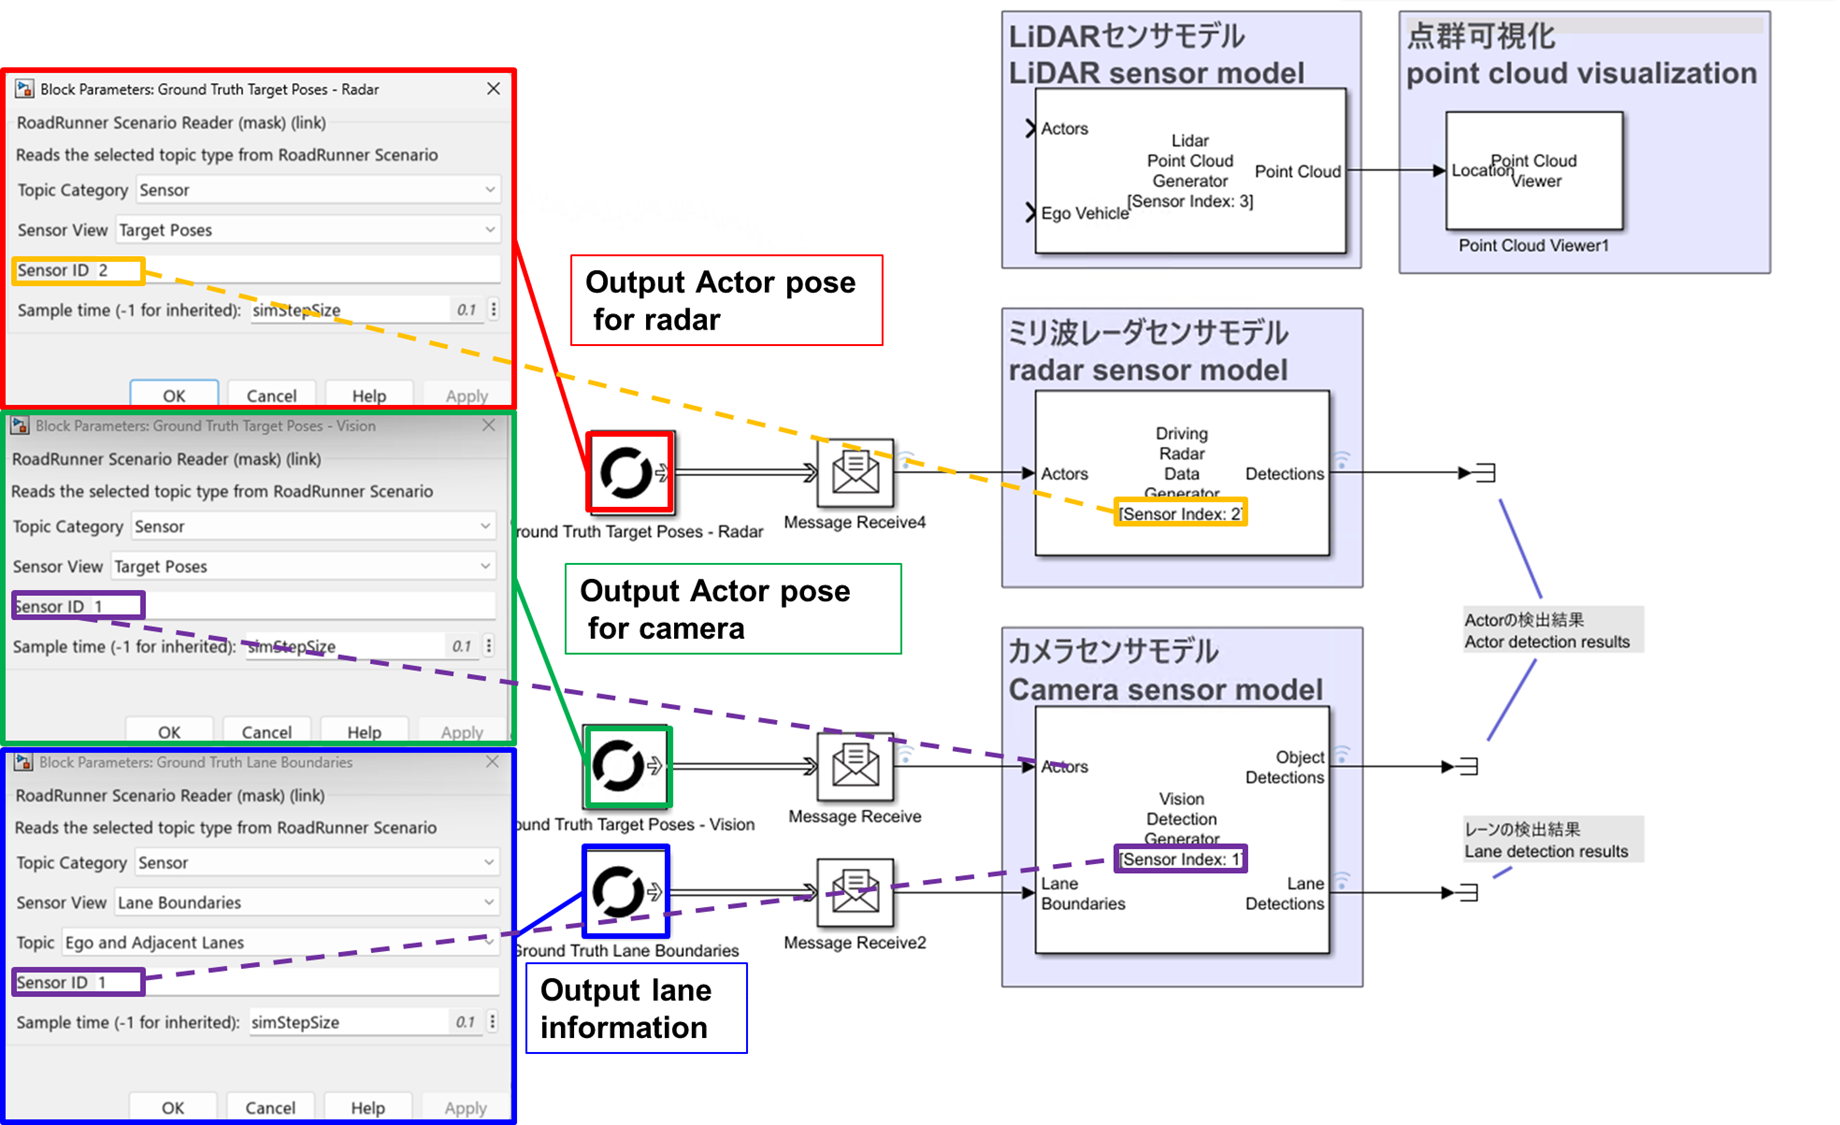

## How to check sensor output

Sensor block output can be checked with Bird's-Eye Scope. The LiDAR sensor can visualize point clouds in 3D using the Point Cloud Viewer block. 

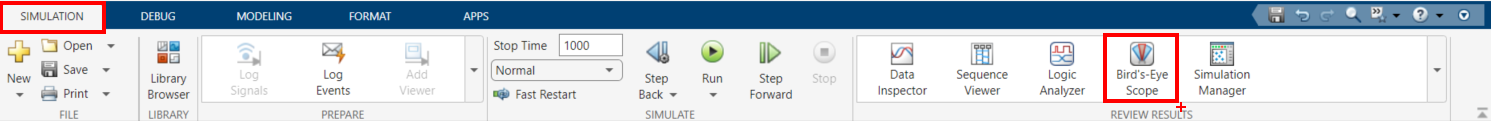

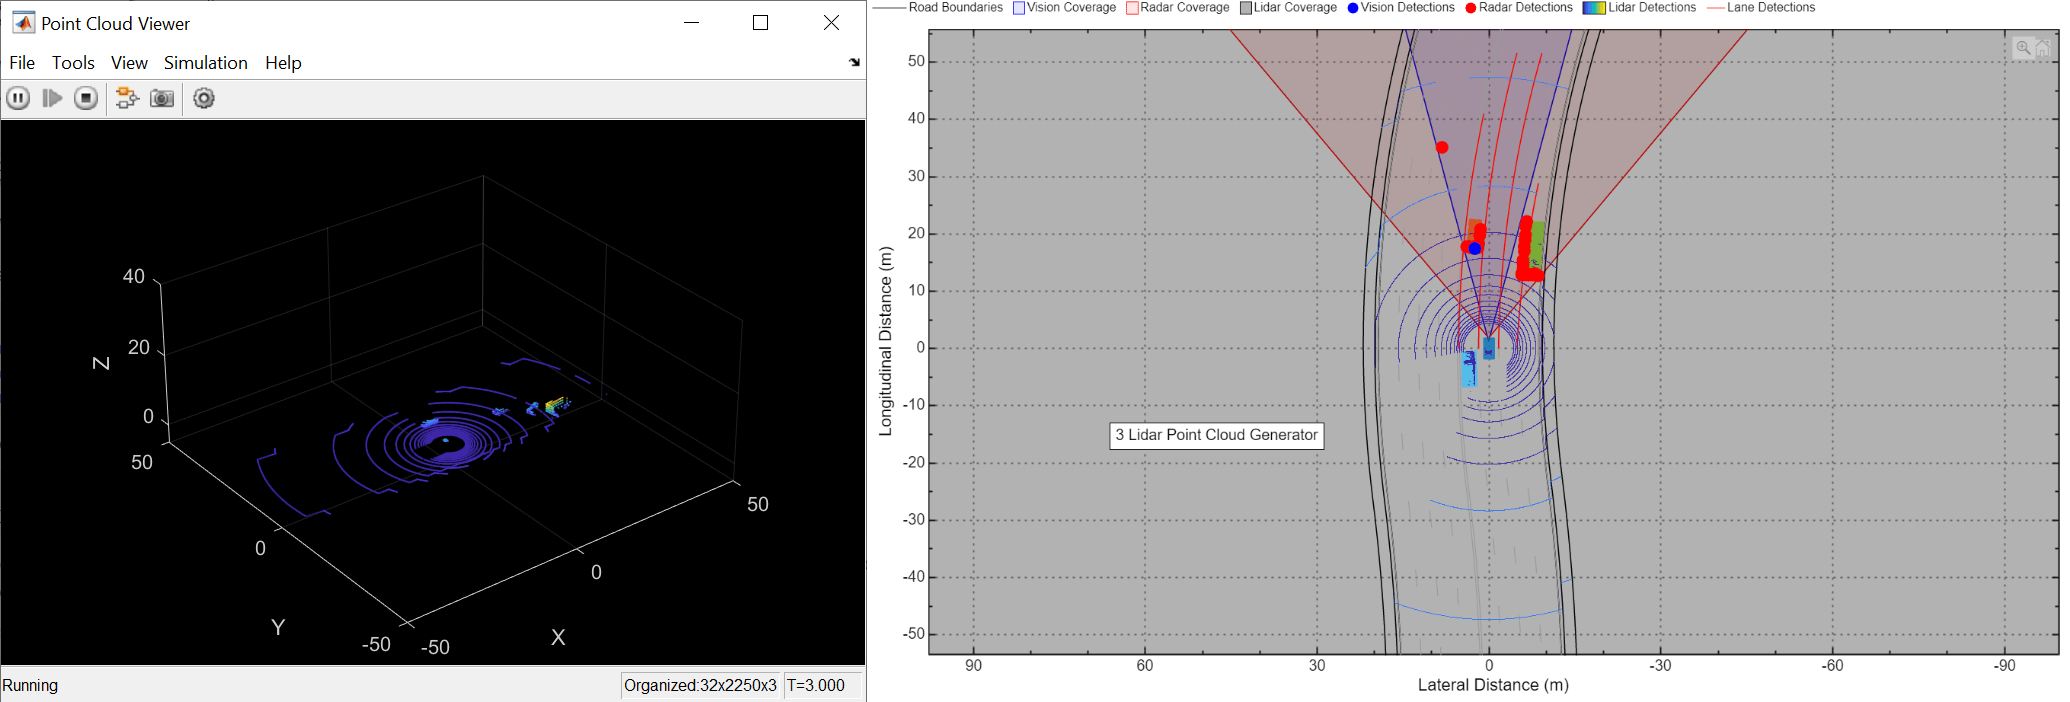

## Add a LiDAR sensor and run RoadRunner

Add Lidar Point Cloud Generator and Point Cloud Viewer 

Since the white vehicle has Actor ID 2, set ActorID of ego vehicle in LiDAR Point Cloud Generator to 2 

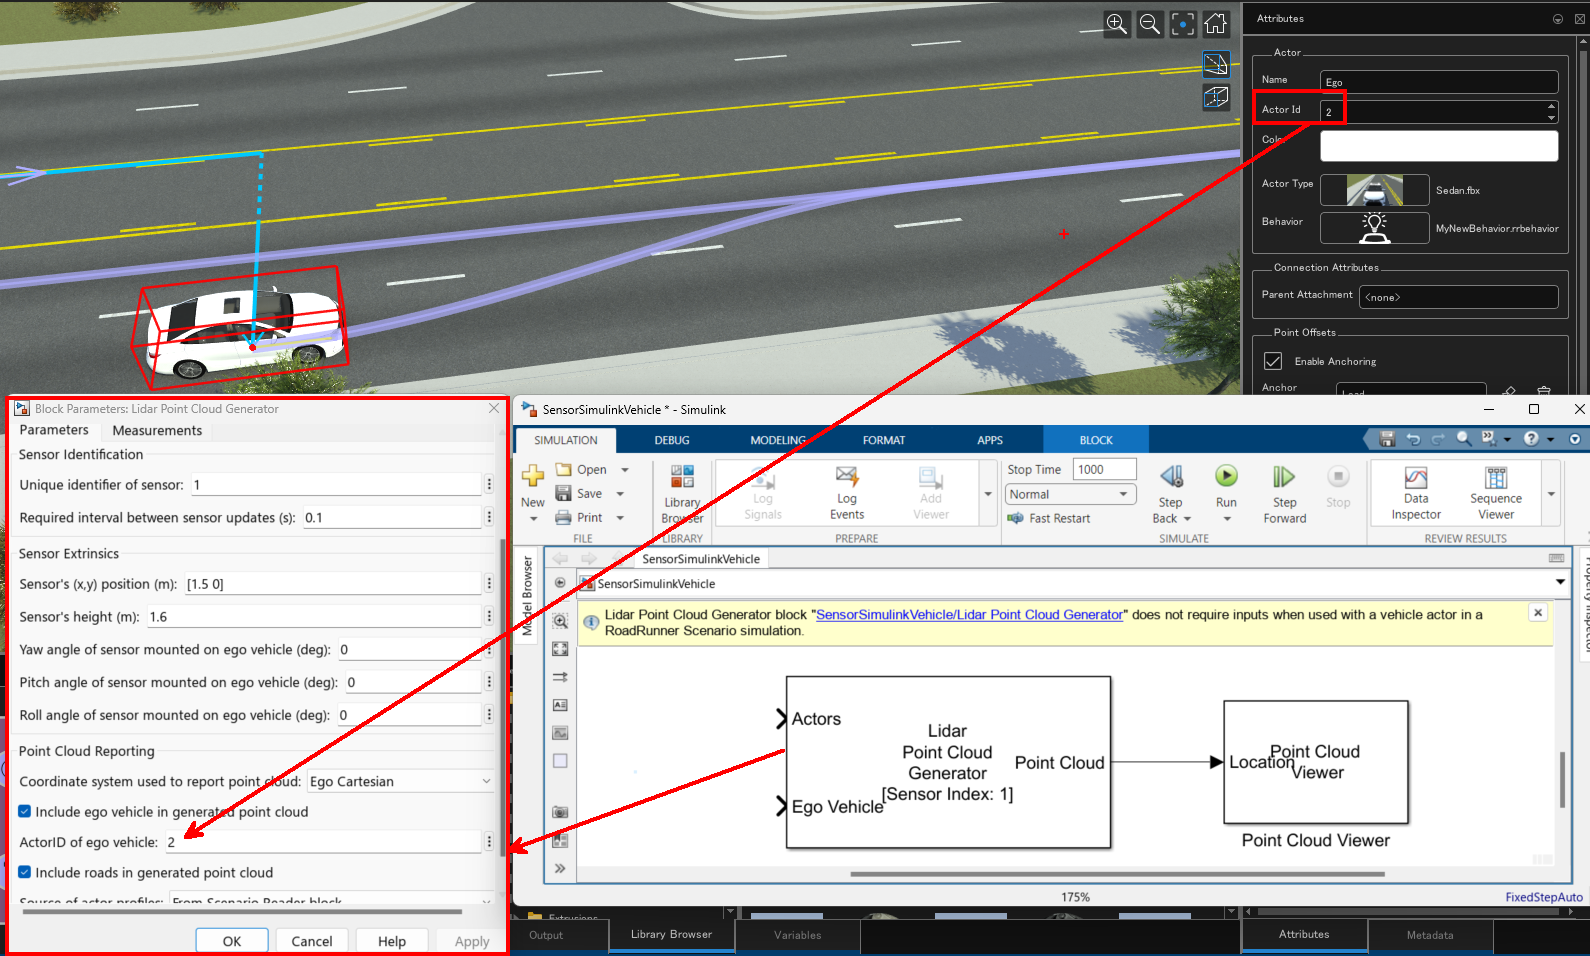

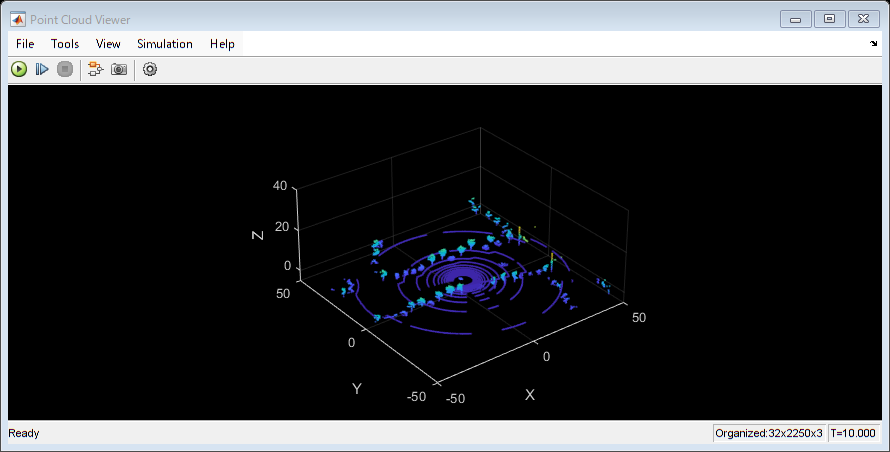

if isSolutionMode
    % Open Simulink model
    model_name = 'SensorSimulinkVehicle.slx';
    open_system(model_name);
    % The above is a model with a LiDAR sensor already added. If you want to use it, change the reference of the Behavior file.
    % (SimulinkVehicle.slx->SensorSimulinkVehicle.slx)

    copyfile("RRfiles/MyLidarSensorSimulation.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
    rrApp.setScenarioVariable("EgoBehavior", "<PROJECT>/Assets/Behaviors/MyLidarSensorSimulation.rrbehavior");
end


% Start the simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end 

## Advanced: Add a camera or millimeter wave radar model and run it

If you want to check the camera and millimeter wave detection points with Bird's-eye Scope, you need to enable Signal logging in the Simulink model settings 

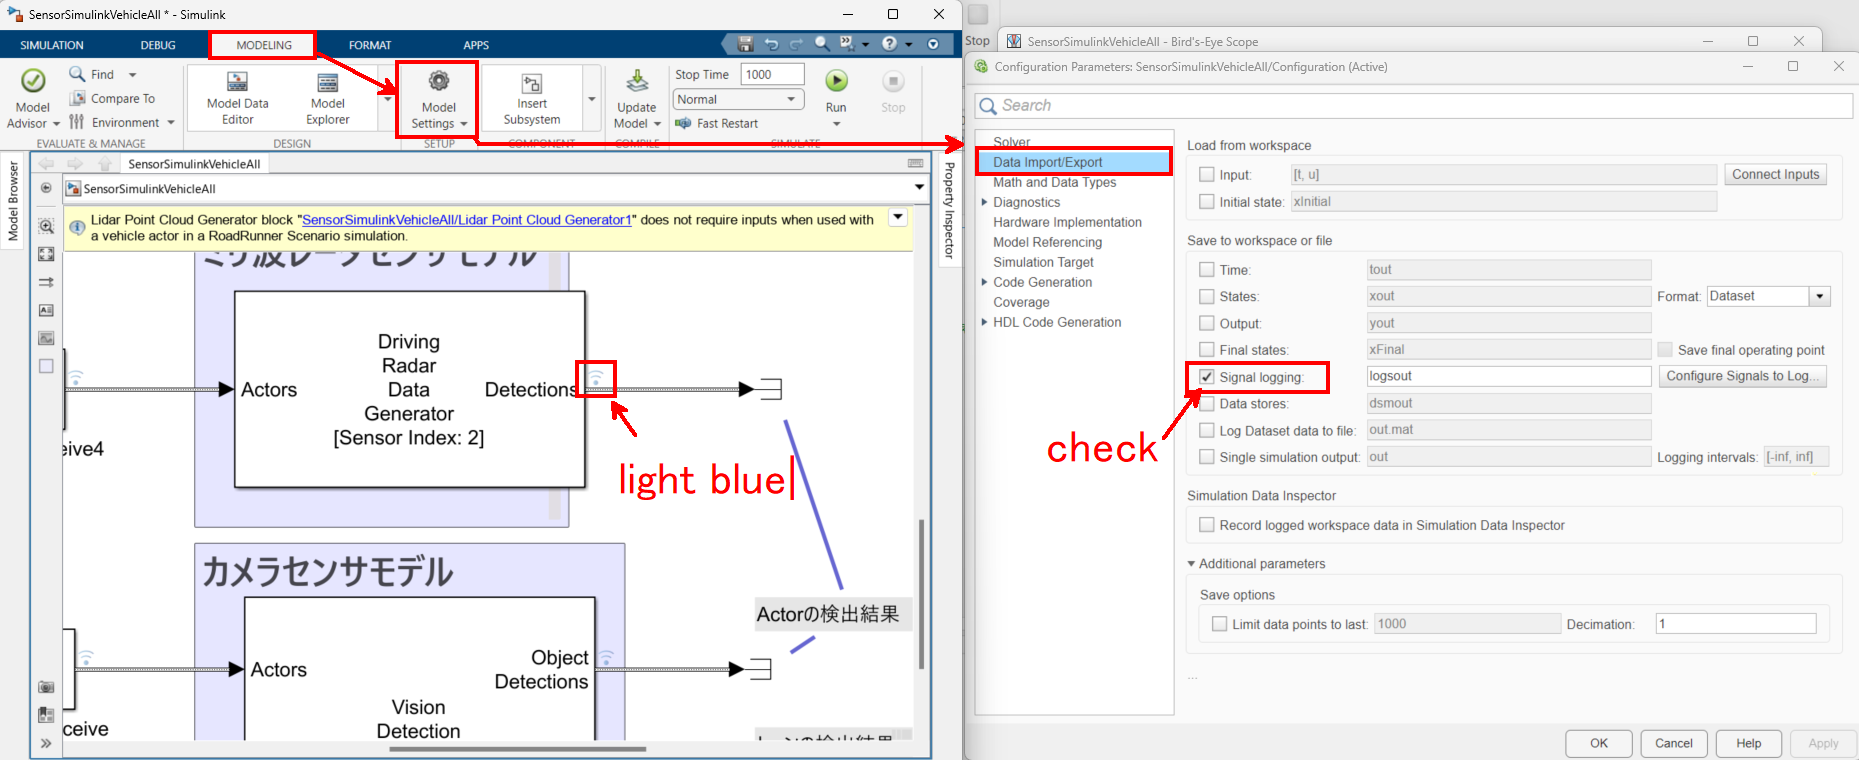

Enable BEV Scope using the following procedure 

- Enable Signal logging 

- Run RoadRunner Scenario and Simulink once 

- Open BEV Scope and click Find Signals (press Find Signals to update before each run) 

- 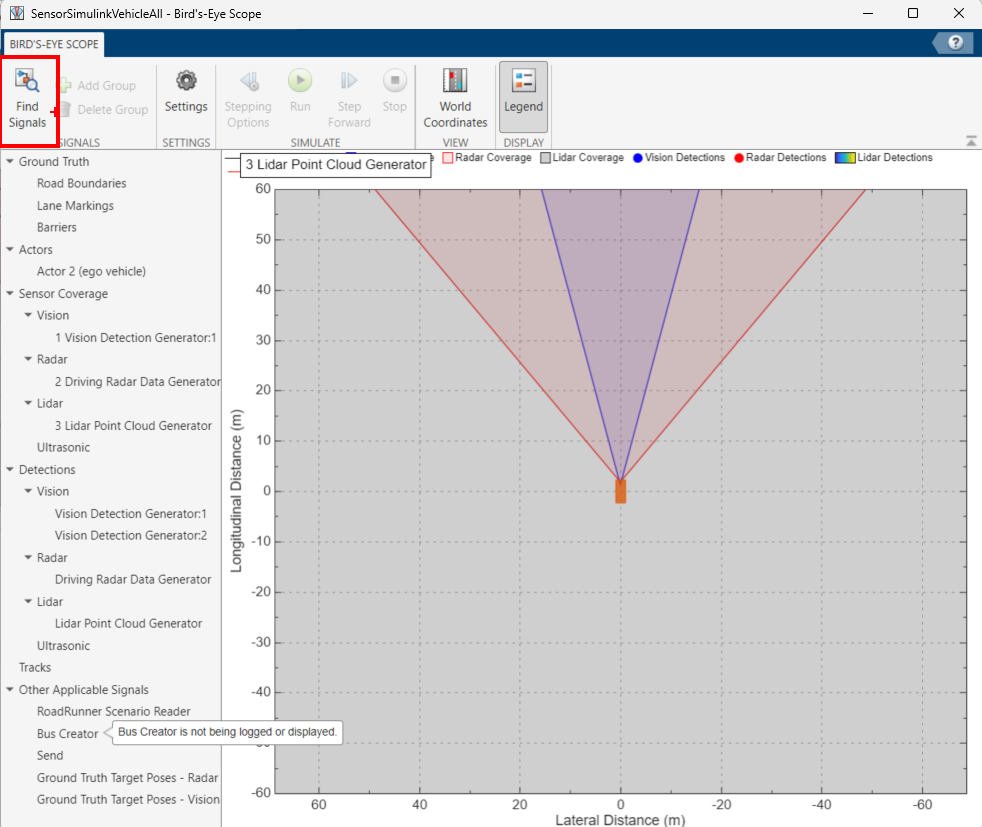

if isSolutionMode
    % Open Simulink model
    model_name = 'SensorSimulinkVehicleAll.slx';
    open_system(model_name);
    % The above is a model with a LiDAR sensor already added. If you want to use it, change the reference of the Behavior file.
    % (SimulinkVehicle.slx->SensorSimulinkVehicle.slx)

    copyfile("RRfiles/MyAllSensorSimulation.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
    rrApp.setScenarioVariable("EgoBehavior", "<PROJECT>/Assets/Behaviors/MyAllSensorSimulation.rrbehavior.rrmeta");
end

if exist("rrSim", "var")
    if class(rrSim) == "Simulink.ScenarioSimulation"
        delete(rrSim);
    end
end

SimClient is shutdown and event thread is stopped!


rrSim = rrApp.createSimulation();
rrSim.set("StepSize", simStepSize);

% Start the simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end